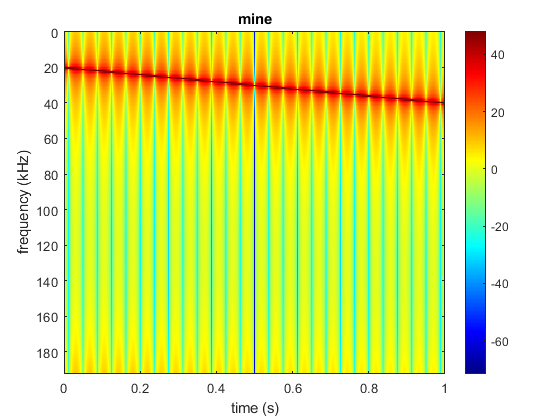

fs=192e3;
fi=20e3;
ff=40e3;
n=1/(fs-1);
t= 0:1/(fs-1):1;
y=chirp(t,fi,1,ff,"linear",0,"complex");
Ns=2^8;
olp=0.5;
win = rectwin(Ns);
slide= floor(Ns*(1-olp));
Nf=floor(1+((fs-Ns)/slide));
stfft= zeros(Ns,Nf);
y=y(:);
for k=0:1:(Nf-1)
    ywin=y(1+(k*slide):(k*slide)+Ns).*win;
    Y=fft(ywin);
    stfft(:,k+1)=Y;
end
fax=(fs*(0:(Nf))/(Nf))*1e-3;
figure();
imagesc(t,fax,20*log10(abs(stfft)));
colorbar;
colormap('jet');
xlabel("time (s)");
ylabel("frequency (kHz)");
title("mine");

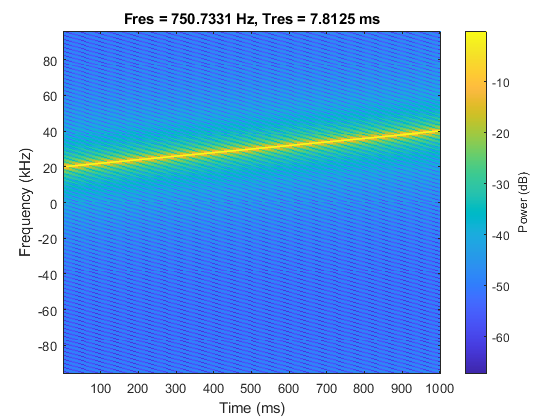

figure();
pspectrum(y,fs,"spectrogram","OverlapPercent",0.5,'Leakage',1);